clear all
figure
intvl =1; %data interval
tres=20; % t0
tmax=1000 % tf

tmax = 1000

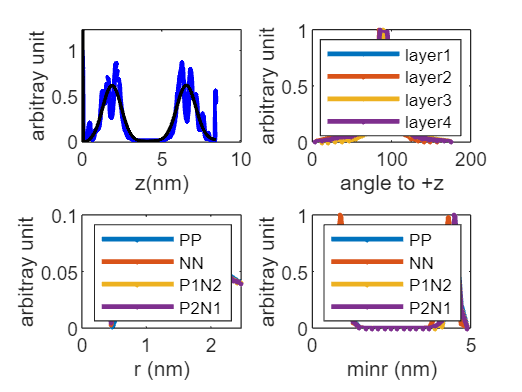

a=readmatrix('C:\Users\41227\Desktop\PO4.txt');
t=a(:,1); %ps
dt=t(2)-t(1); %ps
nintvl=max([1 round(intvl/dt)]); 

P=a(:,2:end); 

a=readmatrix( 'C:\Users\41227\Desktop\NC3.txt');
N=a(:,2:end); 

a=readmatrix('C:\Users\41227\Desktop\C3B.txt');
C35=a(:,2:end); 

%select time
ind3=and(t>tres*1000,t<tmax*1000);%ps
P=P(ind3,:,:);N=N(ind3,:,:);C35=C35(ind3,:,:);

P=reshape(P, [size(P,1) 3 128]);P=permute(P, [1 3 2]);
N=reshape(N, [size(N,1) 3 128]);N=permute(N, [1 3 2]);
C35=reshape(C35, [size(C35,1) 3 128]);C35=permute(C35, [1 3 2]);

P=P(1:nintvl:end,:,:); N=N(1:nintvl:end,:,:); C35=C35(1:nintvl:end,:,:); 

% merge time and index dimensions 
Pm=reshape(P,size(P,1)*size(P,2),size(P,3)); 
Nm=reshape(N,size(N,1)*size(N,2),size(N,3)); 
Cm=reshape(C35,size(C35,1)*size(C35,2),size(C35,3)); 

%%   define layers ########################################################
subplot(2,2,1); title('layer definition (C35 distribution)')

[count,EDGES,BIN] = histcounts(Cm(:,3),300);x=0.5*(EDGES(2:end)+EDGES(1:end-1));
 y=count./max(count);  

xx = mean(x,10); yy = smooth(y,10);
[pks,locs] = findpeaks(yy,'MinPeakProminence',0.05,'MinPeakDistance',20,'Annotate','peaks');

ft = fittype('c+a1*exp(-((x-b1)/sigma1).^2)+a2*exp(-((x-b2)/sigma2).^2)+a3*exp(-((x-b3)/sigma3).^2)+a4*exp(-((x-b4)/sigma4).^2)',...
   'coefficients', {'a1','a2','a3','a4','b1','b2','b3','b4','c','sigma1','sigma2','sigma3','sigma4'},...
    'indep','x'); 

[curve2,gof2] = fit(x',y',ft,'StartPoint',[0.8 0.8 0.8 0.8 ...
    xx(2) xx(locs(2)) xx(locs(4)) xx(locs(5)+30) 0.1 0.5 0.5 0.5 0.5]); 
x0 = linspace(min(x),max(x),1000); 

rat=2;rat2=2;
ind_layer{1}=[min(x) curve2.b1+rat*curve2.sigma1];
ind_layer{2}=[curve2.b2-rat*curve2.sigma2 curve2.b2+rat2*curve2.sigma2];
ind_layer{3}=[curve2.b3-rat2*curve2.sigma3 curve2.b3+rat*curve2.sigma3];
ind_layer{4}=[curve2.b4-rat*curve2.sigma4 max(x)];

%for i=1:4; 
%rectangle('Position',[1 0 1 1],'FaceColor',[0 .5 .5]) 
%hold on 
%end
plot(x-min(x),y,'-b','LineWidth',2); ;drawnow; hold on ; 
plot(x0-min(x),curve2(x0),'-k','LineWidth',1.5);;drawnow;
xlabel('z(nm)');ylabel('arbitray unit');
save('ind_layer','ind_layer')


dPN=sqrt(sum((P - N) .^ 2,3)); dz=N(:,:,3)-P(:,:,3);
dPN_ind=or(dPN>5, abs(dz)>5); %remove cross boundary bonds
% dPN(dPN_ind)=nan; dz(dPN_ind)=nan;

% P1=P(:,:,1);P2=P(:,:,2);P3=P(:,:,3);
% P1(dPN_ind)=nan;P2(dPN_ind)=nan;P3(dPN_ind)=nan; 
% P(:,:,1)=P1;P(:,:,2)=P2;P(:,:,3)=P3;
P1=P(:,:,1);P2=P(:,:,2);P3=P(:,:,3);
P1(dPN_ind)=nan;P2(dPN_ind)=nan;P3(dPN_ind)=nan; 
P(:,:,1)=P1;P(:,:,2)=P2;P(:,:,3)=P3;

N1=N(:,:,1);N2=N(:,:,2);N3=N(:,:,3);
N1(dPN_ind)=nan;N2(dPN_ind)=nan;N3(dPN_ind)=nan; 
N(:,:,1)=N1;N(:,:,2)=N2;N(:,:,3)=N3;
dPN=sqrt(sum((P - N) .^ 2,3)); dz=N(:,:,3)-P(:,:,3);

%%   PN angle      ########################################################
subplot(2,2,2); title('PN angle with +z')

aPN=acos(dz./dPN)/pi*180; 

for i=1:4; 
    ind = and(C35(:,:,3)>ind_layer{i}(1), C35(:,:,3)<ind_layer{i}(2));  
    
    [n,edges] = histcounts(aPN(ind),20); x=0.5*(edges(2:end)+edges(1:end-1)); 
    plot(x,n/max(n),'.-','LineWidth',2); hold on ;drawnow
    leg{i}=['layer' num2str(i)];
    PN_mean(i)=tsnanmean(aPN(ind));
    PN_std(i)=tsnanstd(aPN(ind));
end
legend(leg); xlabel('angle to +z'); ylabel('arbitrary unit');
save('PN_mean_std','PN_mean','PN_std')

%%   interbilayer distancing      #########################################
% interbilayer distancing 
%layer2
subplot(2,2,3); title('interbilayer radial distribution function')
minrPP=[];minrNN=[];minrP1N2=[];minrP2N1=[];
rPP=[];rNN=[];rP1N2=[];rP2N1=[];

for i = 1:size(P,1); %cycle through time 
ind2=and(C35(i,:,3)>ind_layer{2}(1), C35(i,:,3)<ind_layer{2}(2));  
% ind2=and(layer2,dPN_ind); 

ind3=and(C35(i,:,3)>ind_layer{3}(1), C35(i,:,3)<ind_layer{3}(2));  
% ind3=and(layer3,dPN_ind); 


[minrPP_temp, rPP_temp]=distance_pair(squeeze(P(i,ind2,:)),squeeze(P(i,ind3,:))) ;
[minrNN_temp rNN_temp]=distance_pair(squeeze(N(i,ind2,:)),squeeze(N(i,ind3,:))) ;
[minrP1N2_temp rP1N2_temp]=distance_pair(squeeze(P(i,ind2,:)),squeeze(N(i,ind3,:))) ;
[minrP2N1_temp rP2N1_temp]=distance_pair(squeeze(P(i,ind3,:)),squeeze(N(i,ind2,:))) ;

minrPP=[minrPP minrPP_temp];minrNN=[minrNN minrNN_temp];
minrP1N2=[minrP1N2 minrP1N2_temp];minrP2N1=[minrP2N1 minrP2N1_temp];

rPP=[rPP rPP_temp];rNN=[rNN rNN_temp];rP1N2=[rP1N2 rP1N2_temp];rP2N1=[rP2N1 rP2N1_temp];

minrP1N2_t(i)=min(minrP1N2_temp); 
minrP2N1_t(i)=min(minrP2N1_temp); 
minrNN_t(i)=min(minrNN_temp); 
minrPP_t(i)=min(minrPP_temp); 

meanrP1N2_t(i)=mean(rP1N2_temp); 
meanrP2N1_t(i)=mean(rP2N1_temp); 
meanrNN_t(i)=mean(rNN_temp); 
meanrPP_t(i)=mean(rPP_temp); 
end

lim=2.5; %nm  
res=50; 
[r,pr]=radial_pdf(rPP(rPP<lim),res);
plot(r,pr,'.-','LineWidth',2); hold on ;drawnow
rPP_cr=critical_r(r,pr);

[r,pr]=radial_pdf(rNN(rNN<lim),res);
plot(r,pr,'.-','LineWidth',2); hold on ;drawnow
rNN_cr=critical_r(r,pr);

[r,pr]=radial_pdf(rP1N2(rP1N2<lim),res);
plot(r,pr,'.-','LineWidth',2); hold on ;drawnow
rP1N2_cr=critical_r(r,pr);

[r,pr]=radial_pdf(rP2N1(rP2N1<lim),res);
plot(r,pr,'.-','LineWidth',2); hold on ;drawnow
rP2N1_cr=critical_r(r,pr);

legend('PP','NN','P1N2','P2N1');
xlabel('r (nm)'); ylabel('arbitray unit'); % half box width
save('r_critical','rPP_cr','rNN_cr','rP1N2_cr','rP2N1_cr')

%%   minimum distance             #########################################
% 
subplot(2,2,4); title('interbilayer: minimum distance distribution')
[count,EDGES,BIN] = histcounts(minrPP);x=0.5*(EDGES(2:end)+EDGES(1:end-1)); 
plot(x,count/max(count),'.-','LineWidth',2); hold on ;drawnow

[count,EDGES,BIN] = histcounts(minrNN);x=0.5*(EDGES(2:end)+EDGES(1:end-1)); 
plot(x,count/max(count),'.-','LineWidth',2); hold on ;drawnow

[count,EDGES,BIN] = histcounts(minrP1N2);x=0.5*(EDGES(2:end)+EDGES(1:end-1)); 
plot(x,count/max(count),'.-','LineWidth',2); hold on ;drawnow

[count,EDGES,BIN] = histcounts(minrP2N1);x=0.5*(EDGES(2:end)+EDGES(1:end-1)); 
plot(x,count/max(count),'.-','LineWidth',2); hold on ;drawnow


xlabel('minr (nm)'); ylabel('arbitray unit')
legend('PP','NN','P1N2','P2N1');

saveas(gcf,'PN_analysis.fig') 



%%   functions             #########################################


function [min_r,r]=distance_pair(x,y) 
%x=nx3   y=mx3
n=1; 
for i=1:size(x,1); 
    for j=1:size(y,1); 
        r(i,j)=sqrt(tsnansum((x(i,:) - y(j,:)) .^ 2));
        n=n+1; 
    end
end
r(r==0)=nan; 
min_r=tsnanmin(r,[],1);
r=transpose(r(:)); 
end

function [r,pr]=radial_pdf(x,nbin)
x=x(:); 
bin=(linspace(sqrt(min(x)/max(x)),1,nbin)).^2;
bin=bin*max(x); 
for i=1:length(bin)-1;
r(i)=0.5*(bin(i+1)+bin(i));
dr(i)=bin(i+1)-bin(i);
A=pi*(bin(i+1)^2-bin(i)^2); 
n=sum(and(x>bin(i),x<bin(i+1))); 
rho(i)=n/A; 
end
pr=rho/(length(x));
end

function r_cr=critical_r(r,pr) 
[~,I]=max(pr); r_cr0=r(I);
ind=and(r>r_cr0-1,r<r_cr0+2); %use some 
r_i=r(ind);pr_i=pr(ind);
p = polyfit(r_i',pr_i',10);
rfit=linspace(min(r_i),max(r_i),200); 
prfit = polyval(p,rfit);
[~,I]=max(prfit);r_cr=rfit(I);
end